# From Words to Waveforms: Project Walkthrough

ELEC5305 | Zihang Wang | 3 November 2026 A presentation companion for the project video. Run All to reproduce the tables and plots from the supplied measurements. This script summarizes existing measurements; it does not generate music or reanalyse audio.

## 1. Why I did this project

Research question: For one instrumental electronic-music prompt family, do Bright and Dark instructions produce consistent acoustic changes across matched seeds, and how much do other measured attributes change? Spectral centroid is an acoustic indicator associated with brightness. A change in centroid alone does not establish perceived brightness or independent control of timbre. Pitch and instrumentation can also matter. VIDEO: Explain the difference between asking for a change and measuring whether the generated recordings actually show that change.

## 2. What I built and how I tested it

I chose the topic, ran the audio generation, and wrote the original MATLAB code with AI guidance. The integrated Music Feature Lab App supports audio import, original/processed playback, waveform and spectral views, brightness processing, batch analysis and exports. AI assisted integration and analysis. The App analyzes existing audio locally; it does not call the generator.

Dataset: 15 recordings = 3 conditions x 5 matched seeds, approximately 30 seconds each. Conditions: Neutral, Bright and Dark. Seeds: 12315, 12325, 12335, 12345 and 12355. One musical context was tested. Generator: ACE-Step; the installed model/software version was not retained. According to the author's recollection, only brightness wording changed; matching seeds were manually entered, other settings were unchanged, and no generated samples were selectively removed or edited. A complete generation log is unavailable, so these controls are not log-verified.

All conditions use the same MusicAnalysis implementation: channel-average analysis, 20 ms Hamming windows and a nominal 4 ms hop. Target descriptors include amplitude-weighted centroid, spectral slope and high-frequency energy ratio (>= 4 kHz). Other descriptors: RMS, flux and onset rate. RMS is signal amplitude, not a perceptual loudness measure. Onset rate is a detector output, not a direct measurement of musical tempo. VIDEO: Show the App briefly, then return here to explain the experiment.

walkDir = fileparts(mfilename('fullpath'));
if ~isfile(fullfile(walkDir,'data','library_features.csv'))
    walkDir = fileparts(which('Video_Walkthrough.mlx'));
end
assert(isfile(fullfile(walkDir,'data','library_features.csv')), ...
    'Keep this Live Script beside its data folder.');
T = readtable(fullfile(walkDir,'data','library_features.csv'),'TextType','string');
N = sortrows(T(T.Condition=="Neutral",:),'Seed');
B = sortrows(T(T.Condition=="Bright",:),'Seed');
D = sortrows(T(T.Condition=="Dark",:),'Seed');
assert(height(N)==5 && isequal(N.Seed,B.Seed,D.Seed),'Unmatched seeds.');
disp(table(N.Seed,N.Centroid_Hz,B.Centroid_Hz,D.Centroid_Hz, ...
    'VariableNames',{'Seed','Neutral_Hz','Bright_Hz','Dark_Hz'}));

    Seed     Neutral_Hz    Bright_Hz    Dark_Hz
    _____    __________    _________    _______

    12315      971.62       1052.7       971.1 
    12325      2457.9       2306.7      2395.4 
    12335      4408.9       3849.7      3895.6 
    12345      2523.9       2504.7      2431.1 
    12355      3705.8       2971.3      2917.4 



## 3. Did the requested brightness direction occur?

Compare each condition with Neutral at the SAME seed. Positive centroid difference means higher centroid. Expected directions: Bright positive, Dark negative. Direction counts alone do not describe effect magnitude.

brightChange = B.Centroid_Hz-N.Centroid_Hz;
darkChange = D.Centroid_Hz-N.Centroid_Hz;
directionResults = table(["Bright";"Dark"], ...
    [mean(brightChange);mean(darkChange)], ...
    [std(brightChange);std(darkChange)], ...
    [sum(brightChange>0);sum(darkChange<0)],repmat(5,2,1), ...
    'VariableNames',{'Condition','MeanChange_Hz','ChangeSD_Hz', ...
    'ExpectedDirectionCount','Pairs'});
disp(directionResults);

    Condition    MeanChange_Hz    ChangeSD_Hz    ExpectedDirectionCount    Pairs
    _________    _____________    ___________    ______________________    _____

    "Bright"        -276.61         353.39                 1                 5  
    "Dark"          -291.51         343.78                 5                 5  



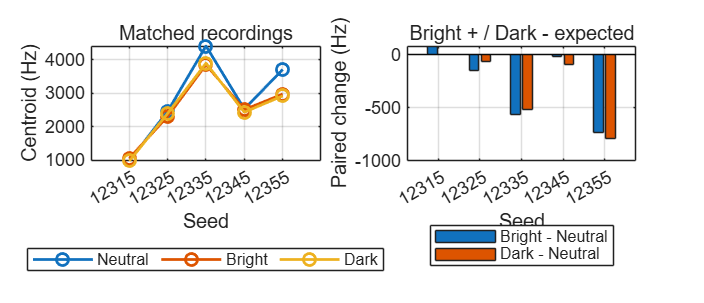

figure('Name','Brightness response by matched seed','Color','w', ...
    'Position',[100 100 1000 430]);
tiledlayout(1,2,'TileSpacing','compact');
nexttile;
plot(1:5,[N.Centroid_Hz B.Centroid_Hz D.Centroid_Hz],'-o','LineWidth',1.4);
xticks(1:5); xticklabels(string(N.Seed)); xtickangle(30);
grid on; xlabel('Seed'); ylabel('Centroid (Hz)');
title('Matched recordings'); set(gca,'FontSize',9);
legend('Neutral','Bright','Dark','Location','southoutside','Orientation','horizontal','FontSize',8);
nexttile;
bar(categorical(string(N.Seed)),[brightChange darkChange]);
yline(0,'k-'); grid on; ylabel('Paired change (Hz)');
xlabel('Seed'); title('Bright + / Dark - expected'); set(gca,'FontSize',9);
legend('Bright - Neutral','Dark - Neutral','Location','southoutside','FontSize',8);

% RESULT: Bright increases centroid in 1/5 pairs; Dark decreases it in 5/5.
% Mean changes are about -277 Hz (Bright) and -292 Hz (Dark). The first Dark
% decrease is only about 0.5 Hz, so not all direction matches are substantial.
% HF ratio increases for Bright in 2/5 pairs and decreases for Dark in 2/5.
% Thus centroid direction is not supported consistently by every descriptor.
% VIDEO: Point to the paired-change chart. Describe the negative finding:
% the word Bright did not reliably raise centroid in this retained sample.

## 4. Did other attributes also change?

Compute paired differences for six descriptors. SD describes variation across five paired changes. It is not a confidence interval or an error in the recording. HF ratio is a fraction, not a percentage-point value.

features = {'Centroid_Hz','HFRatio','Slope_dB_Hz','RMS', ...
    'SpectralFlux','OnsetRate_Hz'};
deltaBright = B{:,features}-N{:,features};
deltaDark = D{:,features}-N{:,features};
neutralSD = std(N{:,features},0,1);
summary = table(string(features(:)),mean(deltaBright,1)',std(deltaBright,0,1)', ...
    mean(deltaDark,1)',std(deltaDark,0,1)',neutralSD', ...
    'VariableNames',{'Feature','BrightMinusNeutral','BrightDeltaSD', ...
    'DarkMinusNeutral','DarkDeltaSD','NeutralSeedSD'});
disp(summary);

       Feature        BrightMinusNeutral    BrightDeltaSD    DarkMinusNeutral    DarkDeltaSD    NeutralSeedSD
    ______________    __________________    _____________    ________________    ___________    _____________

    "Centroid_Hz"            -276.61             353.39            -291.51           343.78          1317.6  
    "HFRatio"               -0.01084           0.017267         -0.0063805         0.011856        0.039065  
    "Slope_dB_Hz"         -3.976e-06         3.9971e-05        -3.2813e-05       7.0739e-05      0.00021793  
    "RMS"                 0.00084037            0.03972           0.018708         0.033209        0.044261  
    "SpectralFlux"        -0.0058857           0.010392           0.016262         0.021934        0.035752  
    "OnsetRate_Hz"          -0.18056            0.42268           -0.15381           1.0883          1.1723  



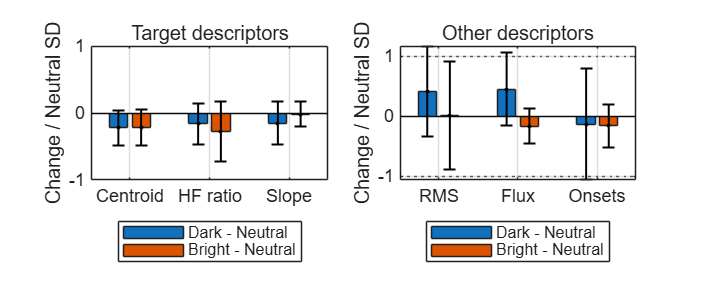

denom = neutralSD; denom(denom==0)=NaN;
change = [mean(deltaDark,1)./denom;mean(deltaBright,1)./denom]';
spread = [std(deltaDark,0,1)./denom;std(deltaBright,0,1)./denom]';
figure('Name','Target and other attribute changes','Color','w', ...
    'Position',[100 100 1050 440]);
tiledlayout(1,2,'TileSpacing','compact');
for panel = 1:2
    nexttile; ids = (1:3)+(panel-1)*3;
    bars = bar(change(ids,:)); hold on;
    for group=1:2
        errorbar(bars(group).XEndPoints,change(ids,group), ...
            spread(ids,group),'k.','LineWidth',1);
    end
    yline(0,'k-'); yline(1,':'); yline(-1,':'); grid on;
    labels = ["Centroid","HF ratio","Slope","RMS","Flux","Onsets"];
    xticks(1:3); xticklabels(labels(ids)); xtickangle(0);
    set(gca,'TickLabelInterpreter','none','FontSize',9);
    ylabel('Change / Neutral SD');
    if panel==1, title('Target descriptors');
    else, title('Other descriptors'); end
    legend('Dark - Neutral','Bright - Neutral','Location','southoutside','FontSize',8);
end

% READ THE FIGURE: bars are mean paired changes; error bars are +/- one
% sample SD of the paired changes, expressed in Neutral-SD units. Dotted
% lines mark +/- one Neutral SD, a descriptive reference, not a significance
% threshold. The denominator describes variation across Neutral recordings,
% not repeatability of one fixed recording. An error bar crossing zero is not
% a statistical test.
% RESULT: other attributes also vary. Their mean changes are smaller than
% their paired-change SDs. This sample does not establish selective control;
% it also does not prove that other attributes are unaffected.
% VIDEO: Explain one row, for example Dark RMS +0.0187 with SD 0.0332.

## 5. Why pitch was excluded from the comparison

An exploratory 440 Hz sinusoid check returned a median estimate of 441 Hz (author-reported MATLAB run). This validates only that simple test signal. For seed 12315, estimates near the 1000 Hz search ceiling comprised 51.0% of finite estimates for Neutral, 33.4% for Bright and 76.5% for Dark (author-reported diagnostic). These are not accuracy percentages. The boundary accumulation makes the reported music medians unsuitable for condition comparison. It does not show that Dark has the highest true pitch. No boundary values were selectively removed to obtain a preferred result. A monophonic estimator does not establish a reliable single pitch for this polyphonic material. Pitch changes therefore remain unresolved.

disp(table(["Neutral";"Bright";"Dark"],[51.0;33.4;76.5], ...
    'VariableNames',{'Condition','NearCeiling_pctOfFiniteEstimates'}));

    Condition    NearCeiling_pctOfFiniteEstimates
    _________    ________________________________

    "Neutral"                    51              
    "Bright"                   33.4              
    "Dark"                     76.5              



% VIDEO: Mention the reliability check briefly; do not interpret pitch order.

## 6. What the DSP reference demonstrates

The App also applies a symmetric FFT-domain spectral tilt to one fixed recording. This is a secondary engineering reference, not a generative model, a listening test or a perceptually matched target for the prompts. Across the nine retained settings, centroid and HF ratio increase with the control. This demonstrates predictable changes for that operation and signal. It does not imply that every descriptor changes in the same way.

calibration = readtable(fullfile(walkDir,'data','calibration.csv'));
disp(calibration);

    Brightness           Source           Duration_s    SampleRate_Hz    Channels    Centroid_Hz    Slope_dB_Hz    Bandwidth_Hz     HFRatio       RMS      Pitch_Hz    SpectralFlux    OnsetRate_Hz
    __________    ____________________    __________    _____________    ________    ___________    ___________    ____________    _________    _______    ________    ____________    ____________

         -1       {'Brightness -1.00'}      91.951          44100           2          692.73       -0.0014943        1993.1       0.0027493    0.20262      NaN         0.13747          8.0151   
      -0.75       {'Brightness -0.75'}      91.951          44100           2           701.1       -0.0015006        2002.5       0.0030135    0.20289      NaN         0.13785          8.0043   
       -0.5       {'Brightness -0.50'}      91.951          44100           2          709.96       -0.0015071        2012.5       0.0033001    0.20315      NaN         0.13825          8.0043   
      -0.25       {

% VIDEO: In the App, load audio, change brightness and show before/after
% spectra. Then distinguish fixed-signal processing from generating new music.

## 7. What I can conclude and what remains

In this one-context, five-seed pilot, prompt response was limited and asymmetric: Dark centroid direction was more consistent than Bright, but effect sizes varied and HF ratio did not consistently agree. The results do not establish independent or perceptually verified brightness control. Same manually specified seeds do not guarantee identical musical content. There is no causal test showing which musical changes drove centroid. Limitations: small sample, one context, incomplete generation provenance, no listening study and unreliable exploratory pitch estimates. Next research steps: retain complete generation settings/version, repeat across more contexts/seeds, and validate a suitable pitch/register method if pitch selectivity is to become a supported claim. VIDEO: End with the contribution: a reproducible acoustic audit and an integrated analysis App, including an honest finding of inconsistent control.

## 8. Personal contribution and AI acknowledgement

The author selected the topic, ran the original music generation, and manually wrote the original MATLAB code with AI guidance. AI assisted experimental design, code guidance, App integration, analysis summaries, report drafting, organization of materials, language editing and grammar checking. This walkthrough and its code were prepared with AI assistance. The author must review the interpretation and understand the submitted work. This walkthrough accompanies the report; references and full methods belong in the report. It does not replace the report, the App or original audio.

fprintf('Walkthrough completed: 15 recordings, 5 matched triplets.\n');

Walkthrough completed: 15 recordings, 5 matched triplets.
